# Test Distribution Function Reconstruction Schemes for Planar Orientation

We can test the accuracy of different functional forms for planar fiber orientation distribution in `DistributionFunctionExamples.mlx` by comparing them to the distributions calculated from the Folgar-Tucker model.  

Start by setting some parameters.  We'll start with simple shear flow for $C_I = 0.05$, with `tend` large enough to be nearly at steady state.

% Problem Parameters
CI    = 0.05;  % Interaction coefficient
xi    = 1;     % Particle shape factor
L     = [0, 1; 0, 0]; % Velocity gradient tensor
D     = (L + L')/2;   % Rate-of-deformation tensor
tend  = 15;    % Final time (use -1 for steady state)
dt    = 0.10;  % Time step
nnod  = 180;   % Number of nodes in phi for psi(phi)
Co    = 0.25;  % Courant number
% Plot appearance
fontsize   = 20;   % Font size for axis labels
legendfont = 16;   % Font size for legends
linewidth  = 1.5;  % Width of plot lines

Edit test parameters and re-run the script to explore other cases.

Next, calculate the orientation distribution function using the Folgar-Tucker model.  Since no initial condition is specified, `solvePsi2D` uses a random initial condition.

[t, psi, phi] = solvePsi2D(L, CI, xi, tend, dt, nnod, Co);

Now find the RMS error in $\psi_\phi$at each time step for a variety of reconstruction schemes.  We'll use Jeffery, ER, Bingham, ME4 with the natural closure, ME4 with the ER closure, ME4 with the non-orthotropic F closure, and ME4 with the exact fourth-order tensor (ME4/A4).

% - RMS errors for various distribution function forms
errJeff = zeros(size(t));
errER   = zeros(size(t));
errBing = zeros(size(t));
errME4  = zeros(size(t));
errME4J = zeros(size(t));
errME4E = zeros(size(t));
errME4F = zeros(size(t));
p = [cos(phi); sin(phi)]; % p vectors for each value of phi
for i = 1:length(t)
    [A, A4] = p2A(p, psi(:,i));  % Orientation tensors at this time step
    % Jeffery distribution
    psiJeff    = JefferyDistn2D(A, nnod);
    errJeff(i) = sqrt(mean( (psi(:,i) - psiJeff').^2 ));
    % Ellipse Radius distribution
    [~, psiER] = fitERdistn2D(A, nnod);
    errER(i)   = sqrt(mean( (psi(:,i) - psiER').^2 ));
    % Bingham distribution
    [~, psiBing] = fitBingham2D(A, nnod);
    errBing(i)  = sqrt(mean( (psi(:,i) - psiBing').^2 ));
    % ME4 distribution
    [~, psiME4] = fitMaxEntropy2D(A4, nnod);
    errME4(i)    = sqrt(mean( (psi(:,i) - psiME4').^2 ));
    % ME4 distribution, natural closure for A4 (Jeffery distn. A4)
    [~, psiME4J] = fitMaxEntropy2D(closeA4planar(A, 'N'), nnod);
    errME4J(i)   = sqrt(mean( (psi(:,i) - psiME4J').^2 ));
    % ME4 distribution, ER closure for A4
    [~, psiME4E] = fitMaxEntropy2D(closeA4planar(A, 'E'), nnod);
    errME4E(i)   = sqrt(mean( (psi(:,i) - psiME4E').^2 ));
    % ME4 distribution, fitted non-orthotropic closure for A4
    [~, psiME4F] = fitMaxEntropy2D(closeA4planar(A, 'F', CI, D), nnod);
    errME4F(i)   = sqrt(mean( (psi(:,i) - psiME4F').^2 ));
end

fprintf('Method   RMS Error @ tend\n')

Method   RMS Error @ tend


fprintf(' Jeffery    %7.2e\n', errJeff(end))

 Jeffery    3.97e-02


fprintf(' Bingham    %7.2e\n', errBing(end))

 Bingham    3.35e-02


fprintf(' ER         %7.2e\n', errER(end))

 ER         2.60e-02


fprintf(' ME4/Nat    %7.2e\n', errME4J(end))

 ME4/Nat    2.46e-02


fprintf(' ME4/ER     %7.2e\n', errME4E(end))

 ME4/ER     2.06e-02


fprintf(' ME4/F      %7.2e\n', errME4F(end))

 ME4/F      8.85e-03


fprintf(' ME4/A4     %7.2e\n', errME4(end))

 ME4/A4     8.45e-03


The second-order reconstructions are similar to one another, and using them as closures for the ME4 reconstruction improves their results somewhat.  However, using more accurate fourth-order information, as in ME4/F and ME4/A4, gives a much smaller error.

Plot the time-dependent RMS errors (provided that `tend` has a positive value)

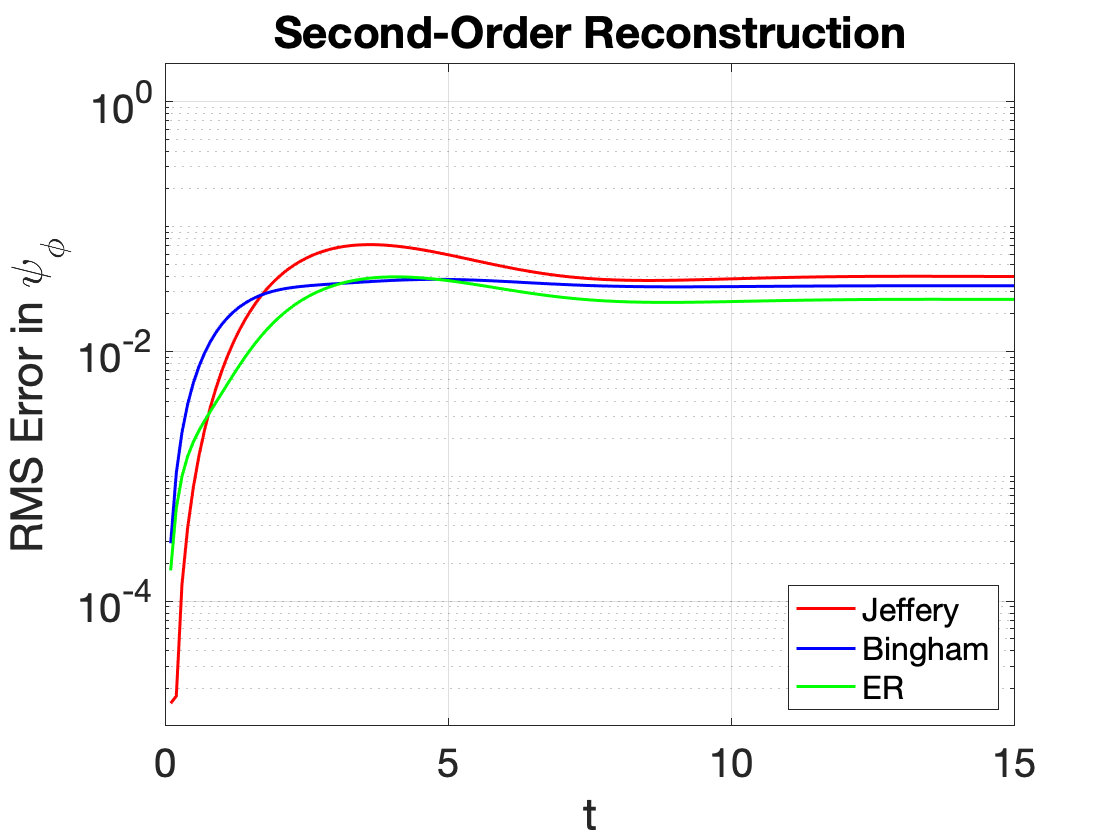

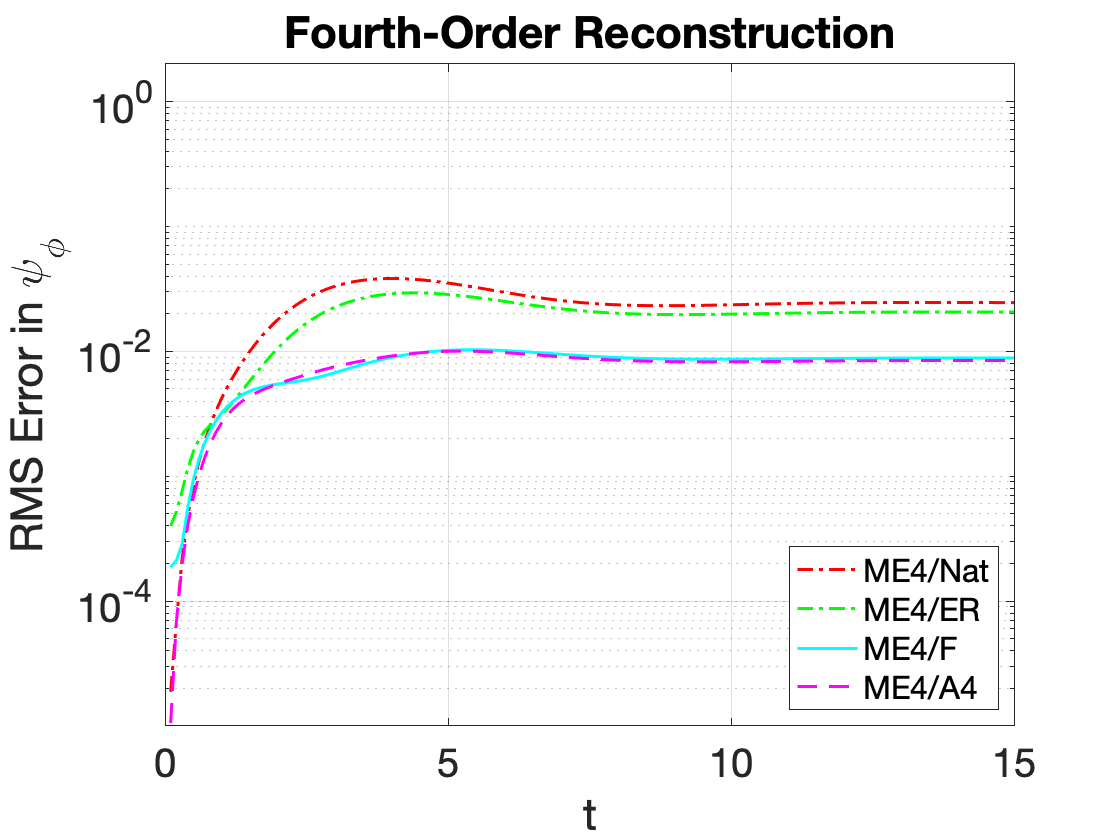

if tend > 0
    % -- Transient errors, second-order fits
    %    We plot from 2:end since the error is zero at the initial
    %    condition and we use a log scale to show large changes in error
    figure(1)
    plot(t(2:end), errJeff(2:end), 'r-', ...
        t(2:end), errBing(2:end), 'b-',  ...
        t(2:end), errER(2:end),   'g-', ...
        'LineWidth', linewidth)
    set(gca, 'FontSize', fontsize, 'Yscale', 'log')
    xlabel('t')
    ylabel('RMS Error in \psi_\phi')
    grid on
    box on
    axval = axis;
    axis([axval(1), axval(2), 1e-5, 2])
    legend('Jeffery', 'Bingham', 'ER', 'Location', 'SouthEast', ...
        'FontSize', legendfont)
    title('Second-Order Reconstruction')
    
    % -- Transient errors, fourth-order fits
    figure(2); clf
    plot(t(2:end), errME4J(2:end), 'r-.', ...
        t(2:end), errME4E(2:end), 'g-.', ...
        t(2:end), errME4F(2:end), 'c-', ...
        t(2:end), errME4(2:end),  'm--', 'LineWidth', linewidth)
    %      t(2:end), errBing(2:end), 'b-', ...
    set(gca, 'FontSize', fontsize, 'Yscale', 'log')
    xlabel('t')
    ylabel('RMS Error in \psi_\phi')
    grid on
    box on
    axis([axval(1), axval(2), 1e-5, 2])
    % axis(axval)  % Match axes of figure(1)
    legend('ME4/Nat', 'ME4/ER', 'ME4/F', ...
        'ME4/A4', 'Location', 'SouthEast', 'FontSize', legendfont)
    title('Fourth-Order Reconstruction')
end

If `tend` is large enough, we can see that the errors are initially small, grow with time, and are close to their maximum values at steady state.  

Finally, take a detailed look at how well each mathematical form fits the calculated distribution function at `tend`.  (You can see snapshots during the transient period by setting tend to a value like 1 or 2 and re-running the script).  We'll do the fourth-order fits first, so that we can match vertical axis values.  (Otherwise the Jeffery distribution's sharp peak can make it hard to see the other second-order data).  

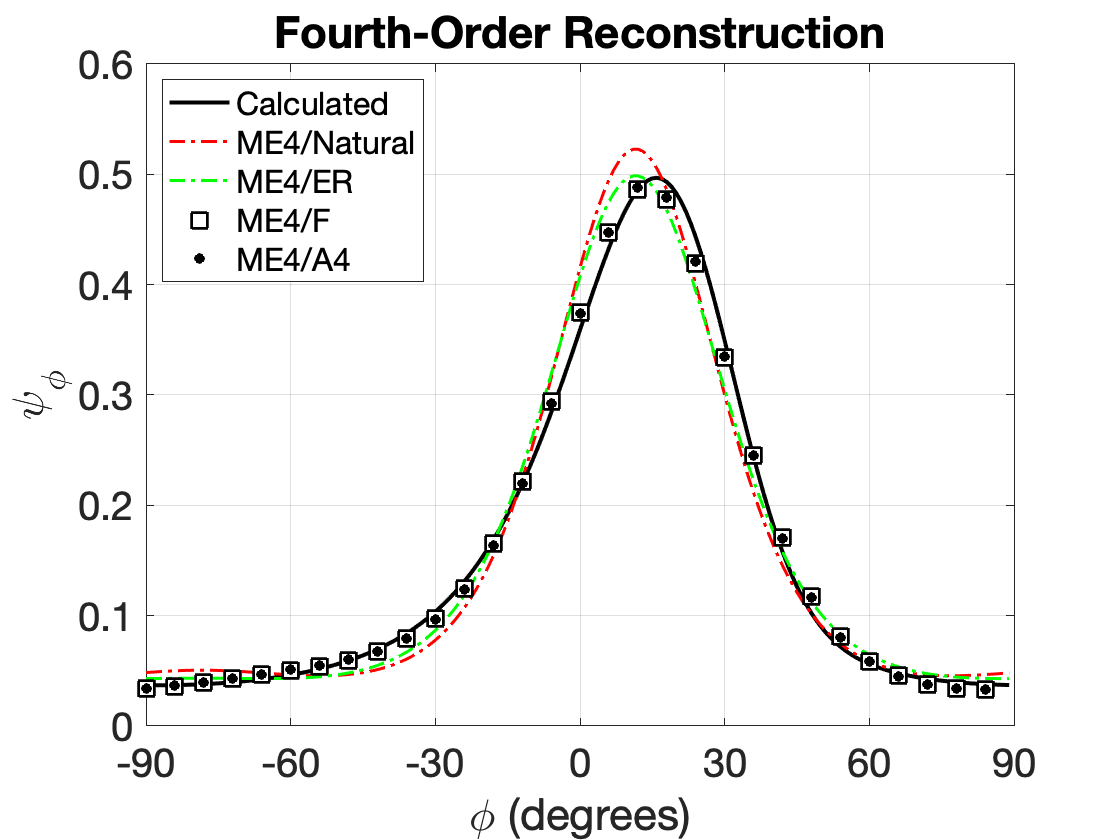

% Fourth-order fits
figure(3); clf
hl4 = plot(rad2deg(phi), psi(:,end), 'k-', ...
    rad2deg(phi), psiME4J,    'r-.', ...
    rad2deg(phi), psiME4E,    'g-.', ...
    rad2deg(phi), psiME4F,    'ks', ...
    rad2deg(phi), psiME4,     'ko', 'LineWidth', linewidth);
set(hl4(1), 'LineWidth', 2)
set(hl4(4), 'MarkerFaceColor', 'w', 'MarkerSize', 10)
set(hl4(5), 'MarkerFaceColor', 'k', 'MarkerSize',  4)
set(hl4, 'MarkerIndices', 1:6:nnod)
set(gca, 'FontSize', fontsize, 'Xtick', -90:30:90)
axval = axis;
axis([-90 90 0, axval(4)])
xlabel('\phi (degrees)')
ylabel('\psi_\phi')
grid on
box on
legend('Calculated', 'ME4/Natural', 'ME4/ER', 'ME4/F','ME4/A4',  ...
    'Location', 'NorthWest', 'FontSize', legendfont)
title('Fourth-Order Reconstruction')

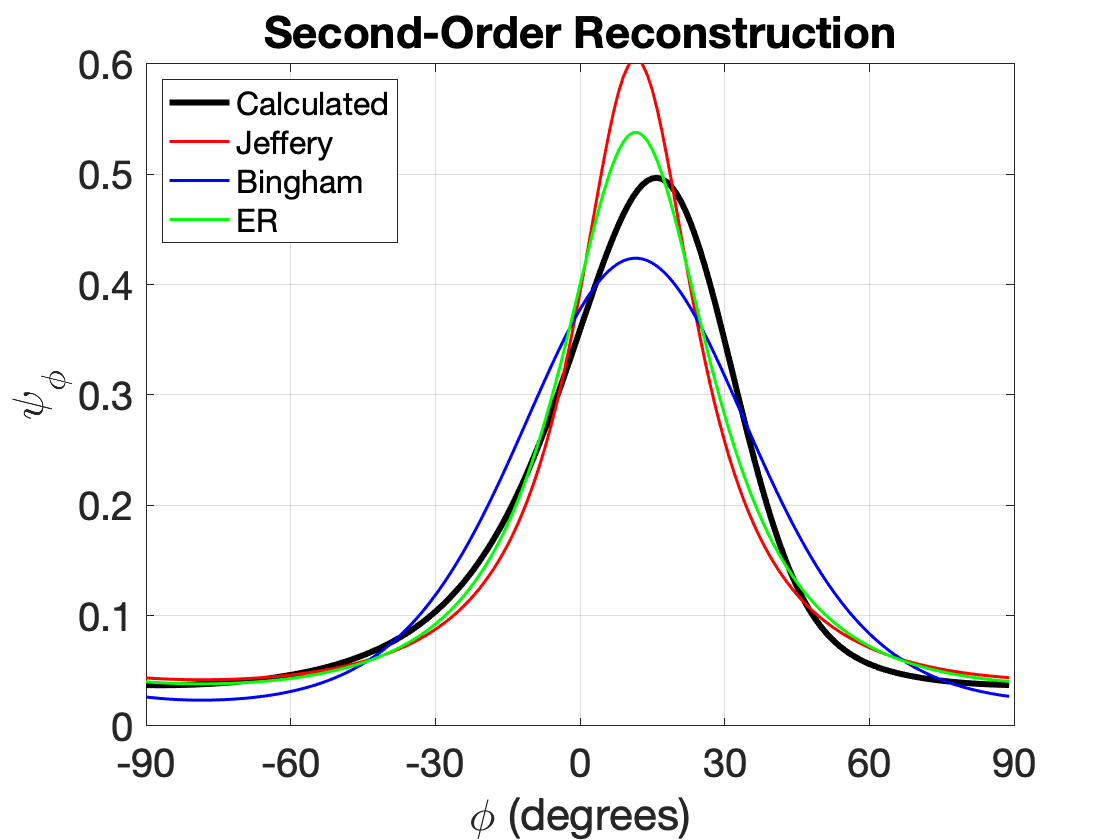


% Second-order fits
figure(4); clf
hl2 = plot(rad2deg(phi), psi(:,end), 'k-', ...
    rad2deg(phi), psiJeff,    'r-', ...
    rad2deg(phi), psiBing,    'b-', ...
    rad2deg(phi), psiER,      'g-', 'LineWidth', linewidth);
set(hl2(1), 'LineWidth', 2*linewidth)
set(hl2(3), 'MarkerFaceColor', 'w')
set(hl2, 'MarkerIndices', 1:6:nnod)
set(gca, 'FontSize', fontsize, 'Xtick', -90:30:90)
axis([-90 90 0, axval(4)])  % Match axis values from the fourth-order plot
xlabel('\phi (degrees)')
ylabel('\psi_\phi')
grid on
box on
legend('Calculated', 'Jeffery', 'Bingham', 'ER', ...
    'Location', 'NorthWest', 'FontSize', legendfont)
title('Second-Order Reconstruction')

The fourth-order reconstructions using ME4 are better, especially ME4/F and ME4/A4, which use the most accurate fourth-order tensor information.  Among the second-order reconstructions, the Jeffery distribution always has too sharp a peak at steady state, while the Bingham distribution has too low a peak (except for planar elongational flow, where it is the exact steady-state solution to the Folgar-Tucker model).  